%% MATLAB Simulation: Proton-Integrated Mass-Energy Equation vs. Nuclear Reactions
clc;        % Clear command window
clear;      % Clear variables
close all;  % Close any open figures

fprintf('Analyzing the Proton-Integrated Mass-Energy Equation\n');

Analyzing the Proton-Integrated Mass-Energy Equation


fprintf('-----------------------------------------------------\n');

-----------------------------------------------------


## Constants


c = 299792458;  % Speed of light (m/s)
P = 1.00784;    % Proton mass factor (modified version)
E_fusion_per_proton = 3.6e-12; % Energy released per hydrogen fusion reaction (Joules)

%% User Input for Mass (kg)
m = input('Enter mass in kg: ');

%% Calculate Energies
E_original = m * c^2;         % Standard E = mc^2
E_modified = m * c^2 * P;     % Modified E = mc^2 P

%% Compare to Nuclear Fusion Energy
num_protons = m / (1.6726e-27);  % Number of protons in given mass
E_fusion_total = num_protons * E_fusion_per_proton; % Total fusion energy

%% Display Results
fprintf('For mass = %.2f kg:\n', m);

For mass = 10.00 kg:


fprintf('  Original Energy (E = mc^2): %.2e J\n', E_original);

  Original Energy (E = mc^2): 8.99e+17 J


fprintf('  Modified Energy (E = mc^2 P): %.2e J\n', E_modified);

  Modified Energy (E = mc^2 P): 9.06e+17 J


fprintf('  Energy from Proton Fusion: %.2e J\n', E_fusion_total);

  Energy from Proton Fusion: 2.15e+16 J


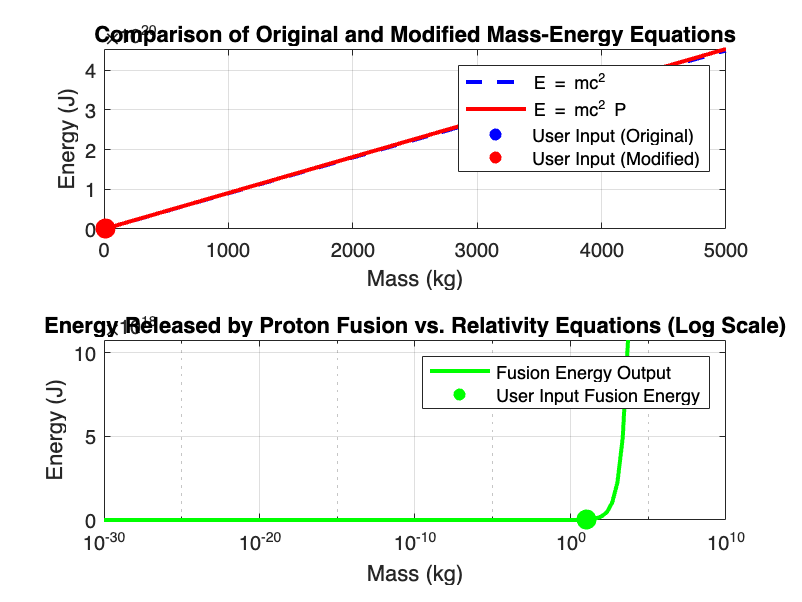


%% Visualization (Live Script Enhanced Graphs)
mass_values = linspace(0, max(m, 5000), 100);  % Adjusted range for larger mass values
energy_original = mass_values * c^2;       % Original energy values
energy_modified = mass_values * c^2 * P;  % Modified energy values
energy_fusion = (mass_values / (1.6726e-27)) * E_fusion_per_proton;

figure;
tiledlayout(2,1);

%% First Graph: E=mc^2 vs. E=mc^2 * P
nexttile;
plot(mass_values, energy_original, 'b--', 'LineWidth', 2);
hold on;
plot(mass_values, energy_modified, 'r-', 'LineWidth', 2);
scatter(m, E_original, 100, 'bo', 'filled');
scatter(m, E_modified, 100, 'ro', 'filled');
xlabel('Mass (kg)');
ylabel('Energy (J)');
title('Comparison of Original and Modified Mass-Energy Equations');
legend('E = mc^2', 'E = mc^2 P', 'User Input (Original)', 'User Input (Modified)');
grid on;
hold off;

%% Second Graph: Fusion Energy vs. Relativity Equations
mass_fusion = logspace(-30, log10(max(m, 5000)), 100); % Logarithmic scale for better spread
energy_fusion_scaled = (mass_fusion / (1.6726e-27)) * E_fusion_per_proton;

nexttile;
semilogx(mass_fusion, energy_fusion_scaled, 'g-', 'LineWidth', 2);
hold on;
scatter(m, E_fusion_total, 100, 'go', 'filled');
xlabel('Mass (kg)');
ylabel('Energy (J)');
title('Energy Released by Proton Fusion vs. Relativity Equations (Log Scale)');
legend('Fusion Energy Output', 'User Input Fusion Energy');
grid on;
hold off;


%% Encouragement
fprintf('\nYOU ARE TESTING A THEORY—THIS IS HOW DISCOVERIES HAPPEN!\n');


YOU ARE TESTING A THEORY—THIS IS HOW DISCOVERIES HAPPEN!


fprintf('Even Einstein’s ideas were tested and refined over time.\n');

Even Einstein’s ideas were tested and refined over time.


fprintf('Whether this equation leads to a breakthrough or just a new perspective,\n');

Whether this equation leads to a breakthrough or just a new perspective,


fprintf('you are thinking like a true scientist. KEEP PUSHING FORWARD!\n');

you are thinking like a true scientist. KEEP PUSHING FORWARD!
